# Tap 1 - Métodos numéricos - 2023 - 0

**Integrantes:**

- Sofía Herrera Salazar

- Melanie Cortez Rojas

- Ximena Nicolle Lindo Peña

- Luis David Golac Córdova

- Valeria Nicole Espinoza Tarazona

# 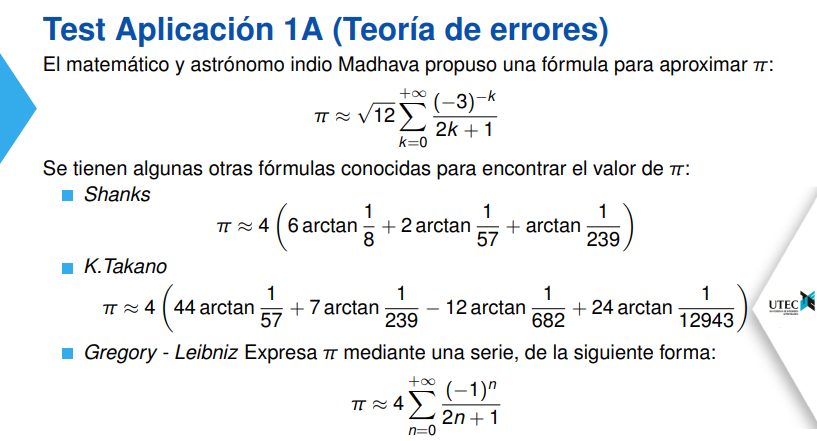

format long

Declaración de la variable π

pi_base = pi

pi_base =    3.141592653589793


Declaración de π en base a la formula de Shanks

pi_Shanks = 4*( 6 * atan(1/8) + 2 * atan(1/57) + atan(1/239))

pi_Shanks =    3.141592653589793


Declaración de π en base a la formula de K. Takano

pi_KTakano = 4 * (44 * atan(1/57) + 7 * atan(1/239) - 12 * atan(1/682) + 24 * atan(1/12943))

pi_KTakano =    3.141592653589793


Declaración del vector para guardar los 25 terminos segun la formula de Medahava

aprox_Medhava=[];
aprox = 0; % Variable para acumular la suma de formula
for k = 0:24
    aprox = aprox + ((-3)^-k)/(2*k + 1);
    var = (sqrt(12) * aprox); % Se multiplica por √12 aparte, para no afectar la suma
    aprox_Medhava = [aprox_Medhava; var]; % Se almacena la aproximación n-esimo termino
end

Vector con los 25 terminos de la formula de Medhava

aprox_Medhava

aprox_Medhava =    3.464101615137754
   3.079201435678004
   3.156181471569954
   3.137852891595680
   3.142604745663085
   3.141308785462883
   3.141674312698838
   3.141568715941784
   3.141599773811506
   3.141590510938080


Declaración de pi en base a la formula de Medhava

pi_Medhava = var

pi_Medhava =    3.141592653589854


Declaración del vector para guardar los 25 terminos segun la formula de Gregory-Leibniz

aprox_Gregory=[];
aprox=0; % Variable para acumular la suma de formula
for n = 0:24
    aprox=aprox+((-1)^n)/(2*n+1);
    var=aprox*4; % Se multiplica por 4 aparte, para no afectar la suma
    aprox_Gregory = [aprox_Gregory; var]; % Se almacena la aproximación n-esimo termino
end

Vector con los 25 terminos de la formula de Gregory-Leibniz

aprox_Gregory

aprox_Gregory =    4.000000000000000
   2.666666666666667
   3.466666666666667
   2.895238095238096
   3.339682539682540
   2.976046176046176
   3.283738483738484
   3.017071817071818
   3.252365934718877
   3.041839618929403


Declaración de pi en base a la formula de Gregory-Leibniz

pi_Gregory = var

pi_Gregory =    3.181576685435032


Calculo de las cifras significativas para pi en base la formula de Shanks

cifras_Shanks = 0;
while (abs(pi_Shanks - pi_base)/pi_base) < 5*10^-(cifras_Shanks+1)
    cifras_Shanks = cifras_Shanks + 1;
end

Calculo de las cifras significativas para pi en base la formula de K. Takano

cifras_KTakano = 0;
while (abs(pi_KTakano - pi_base)/pi_base) < 5*10^-(cifras_KTakano+1)
    cifras_KTakano = cifras_KTakano + 1;
end

Calculo de las cifras significativas para pi en base la formula de Medhava

cifras_Medhava = 0;
while (abs(pi_Medhava - pi_base)/pi_base) < 5*10^-(cifras_Medhava+1)
    cifras_Medhava = cifras_Medhava + 1;
end

Calculo de las cifras significativas para pi en base la formula de Gregory-Leibniz

cifras_Gregory = 0;
while (abs(pi_Gregory - pi_base)/pi_base) < 5*10^-(cifras_Gregory+1)
    cifras_Gregory = cifras_Gregory + 1;
end

cifras_Shanks

cifras_Shanks =    323


cifras_KTakano

cifras_KTakano =    323


cifras_Medhava

cifras_Medhava =     14


cifras_Gregory

cifras_Gregory =      2


Comparando los resultados en base a las cifras significativas de cada pi, se puede apreciar que las aproximaciones mas cerca al valor de pi por Matlab son la de las formulas de Shanks y K. Takano. No obstante el valor de pi para las formulas de Medhava y Gregory-Leibniz no son tan precisas ya que los valores obtenidos estan limitados a 25 terminos, quizas con mas terminos puedan llegar a aproximarse aun mas.

aprox = 0;
n = 0;
cifras = 0;
while cifras ~= 4 % While creado para que el problema itere hasta que el pi segun la formula
                  % de Gregory - Leibniz se aproxima al pi de MATLAB en
                  % cuatro cifras
	aprox=aprox+((-1)^n)/(2*n+1);
	var=aprox*4;
    cifras = 0;
    while (abs(var - pi_base)/pi_base) < 5*10^-(cifras+1) % Calcula la cantidad de cifras
                                                          % significativas
                                                          % en el n-esimo termino
        cifras = cifras + 1;
    end
    n = n + 1;
end

n

n =    637


Como se puede apreciar, el minimo de terminos de la serie requeridos para aproximar el pi de MATLAB al pi segun la formula de Gregory - Leibniz con cuatro cifras significativas es 637

aprox = 0;
n = 0;
cifras = 0;
while cifras ~= 4 % While creado para que el problema itere hasta que el pi segun la formula
                  % de Medhava se aproxima al pi de MATLAB en cuatro cifras
    aprox = aprox + ((-3)^-n)/(2*n + 1);
    var = (sqrt(12) * aprox);
    cifras = 0;
    while (abs(var - pi_base)/pi_base) < 5*10^-(cifras+1) % Calcula la cantidad de cifras
                                                          % significativas
                                                          % en el n-esimo termino
        cifras = cifras + 1;
    end
    n = n + 1;
end

n

n =      5


Como se puede apreciar, el minimo de terminos de la serie requeridos para aproximar el pi de MATLAB al pi segun la formula de Medhava con cuatro cifras significativas es 5

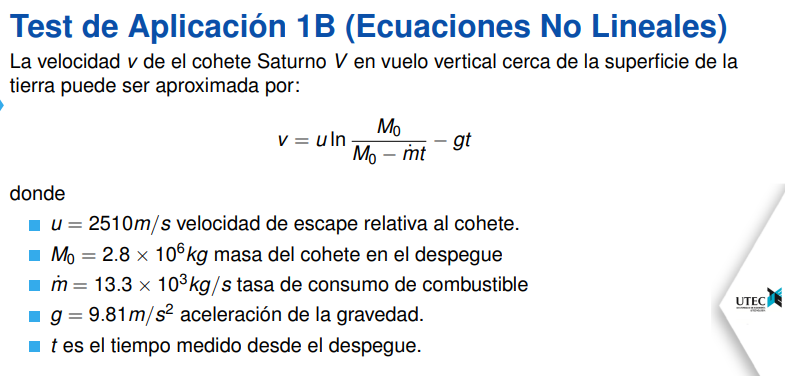

syms t
F=(2510*log(2.8*((10^(6))/(2.8*10^(6)-13.3*10^(3)*t)))-9.81*t-335) %funcion

$$F = 2510\,\log\left(-\frac{2800000}{13300\,t-2800000}\right)-\frac{981\,t}{100}-335$$

f=matlabFunction(F) %formato nuevo de funcion

f = function_handle with value:
    @(t)t.*(-9.81e+2./1.0e+2)+log(-2.8e+6./(t.*1.33e+4-2.8e+6)).*2.51e+3-3.35e+2


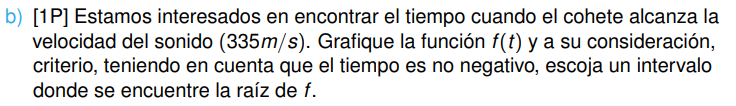

x=0; %lim 1=0 porque el tiempo es positivo
y=100; %lim 2
fplot(f,[0 100]); %gráfica
grid on

fzero(f,60); %raíz más cercana de x=60
if f(x)*f(y)<0
    fprintf('Existe al menos una raiz') 
    %si f evaluado en x y y es menor a 0, significa que existe una raíz
else
    fprintf('No se puede afirmar que existe una raiz')
end

Existe al menos una raiz

disp('La raíz se encuentra entre 60 y 80 acorde al gráfico')

La raíz se encuentra entre 60 y 80 acorde al gráfico


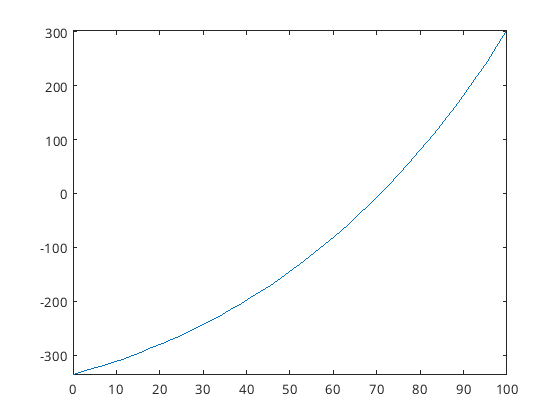

grid off

biseccion2(f,x,y,10^(-3)) %cantidad de iteracciones necesitadas

Se necesita 16 iteraciones


raiz =   70.877838134765625


logitud =      7.629394531250000e-04


ans = 	1.0e+02 *

                   0   1.000000000000000   0.500000000000000  -3.350000000000000   3.013361111401882  -1.449065460435686   0.500000000000000
   0.500000000000000   1.000000000000000   0.750000000000000  -1.449065460435686   3.013361111401882   0.347665157805197   0.250000000000000
   0.500000000000000   0.750000000000000   0.625000000000000  -1.449065460435686   0.347665157805197  -0.640513100907261   0.125000000000000
   0.625000000000000   0.750000000000000   0.687500000000000  -0.640513100907261   0.347665157805197  -0.170836835125760   0.062500000000000
   0.687500000000000   0.750000000000000   0.718750000000000  -0.170836835125760   0.347665157805197   0.082037312686366   0.031250000000000
   0.687500000000000   0.718750000000000   0.703125000000000  -0.170836835125760   0.082037312686366  -0.045958341324626   0.015625000000000
   0.703125000000000   0.718750000000000   0.710937500000000  -0.045958341324626   0.082037312686366   0.017645480288663   0.00781250000

x0=68 %valor x0

x0 =     68


error=1; 
z=[x0]; %comienza por el valor dado
Tol=1e-3;
newton(f,x0,Tol) %Se necesitarian 3 iteraciones

ans =   68.000000000000000
  70.944466620906027
  70.878007107762869


syms t
%1-Despejando t de 13.3*10^3*t
g1=@(t)(((2.8*10^6)/exp((9.81*t+335)/2510)-2.8*10^6)/13.3*10^3)

g1 = function_handle with value:
    @(t)(((2.8*10^6)/exp((9.81*t+335)/2510)-2.8*10^6)/13.3*10^3)


for i=60:80
    g1(i)
end

ans =     -6.481279125220060e+07


ans =     -6.538118165249519e+07


ans =     -6.594735491029613e+07


ans =     -6.651131967409723e+07


ans =     -6.707308455865674e+07


ans =     -6.763265814512901e+07


ans =     -6.819004898119548e+07


ans =     -6.874526558119541e+07


ans =     -6.929831642625582e+07


ans =     -6.984920996442102e+07


ans =     -7.039795461078179e+07


ans =     -7.094455874760373e+07


ans =     -7.148903072445554e+07


ans =     -7.203137885833625e+07


ans =     -7.257161143380269e+07


ans =     -7.310973670309560e+07


ans =     -7.364576288626598e+07


ans =     -7.417969817130052e+07


ans =     -7.471155071424673e+07


ans =     -7.524132863933751e+07


ans =     -7.576904003911529e+07



%2-Despejando t de 9.81*t
g2=@(t)((2510*log(2.8*((10^(6))/(2.8*10^(6)-13.3*10^(3)*t)))-335)/9.81)

g2 = function_handle with value:
    @(t)((2510*log(2.8*((10^(6))/(2.8*10^(6)-13.3*10^(3)*t)))-335)/9.81)


for i=60:80
    g2(i)
end

ans =   51.685684819898533


ans =   53.391134373300446


ans =   55.108027961270473


ans =   56.836520207183540


ans =   58.576768889477123


ans =   60.328935028077176


ans =   62.093182973804161


ans =   63.869680500882964


ans =   65.658598902686393


ans =   67.460113090850029


ans =   69.274401697900970


ans =   71.101647183551023


ans =   72.942035944813242


ans =   74.795758430107227


ans =   76.663009257528330


ans =   78.543987337463733


ans =   80.438895999750414


ans =   82.347943125575142


ans =   84.271341284333872


ans =   86.209307875673659


ans =   88.162065276955019



%No se podría resolver con punto fijo debido a que no cumple la condicion
%de:g(x) pertenece al intervalo [a,b] para cualquier x dentro del intervalo
%[a,b]. En los dos casos, despejando t y evaluando la función dentro del
%intervalo de 60 a 80, no dan valores del intervalo.

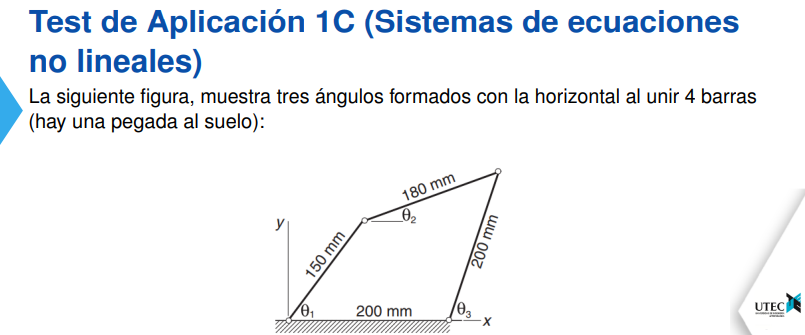

syms x y z
%x= theta(1), y=theta(2), z=theta(3)
G=[150*cos(x)+180*cos(y)-200-200*cos(z);150*sin(x)+180*sin(y)-200*sin(z)]

$$G = \left(\begin{array}{c} 150\,\cos\left(x\right)+180\,\cos\left(y\right)-200\,\cos\left(z\right)-200\\ 150\,\sin\left(x\right)+180\,\sin\left(y\right)-200\,\sin\left(z\right) \end{array}\right)$$

clear z

%se convierte 75° a radianes, lo cual es 1.309
G=[150*cos(x)+180*cos(y)-200-200*cos(1.309);150*sin(x)+180*sin(y)-200*sin(1.309)]

$$G = \left(\begin{array}{c} 150\,\cos\left(x\right)+180\,\cos\left(y\right)-\frac{35432522916489541}{140737488355328}\\ 150\,\sin\left(x\right)+180\,\sin\left(y\right)-\frac{3398552155689287}{17592186044416} \end{array}\right)$$

G=matlabFunction(G) 

G = function_handle with value:
    @(x,y)[cos(x).*1.5e+2+cos(y).*1.8e+2-2.517632176796492e+2;sin(x).*1.5e+2+sin(y).*1.8e+2-1.931853237061482e+2]


dF = jacobian(G(x,y),[x,y])%da el jacobiano

$$dF = \left(\begin{array}{cc} -150\,\sin\left(x\right) & -180\,\sin\left(y\right)\\ 150\,\cos\left(x\right) & 180\,\cos\left(y\right) \end{array}\right)$$

%Punto 1
x0 = [0;2] % se elije (0,2) porque es un número que está en el intervalo que

x0 =      0
     2


%proporciona ángulos indicados
tol = 1e-3

tol =      1.000000000000000e-03


z1 = newtonraphson(G,x0,tol)

$$dF = \left(\begin{array}{cc} -150\,\sin\left(x\right) & -180\,\sin\left(y\right)\\ 150\,\cos\left(x\right) & 180\,\cos\left(y\right) \end{array}\right)$$

z1 =                    0   2.000000000000000   1.000000000000000
  -0.342282748493229   0.920597356901257   1.172502435518636
   0.222346456202620   1.108518926351157   0.509354591314381
   0.311284331283265   0.933977125463133   0.186880166686602
   0.347650393321182   0.909050059679821   0.040004465816465
   0.349385628745900   0.907526575464104   0.001912049158264
   0.349390667778865   0.907522349033536   0.000005552516663


sol1 = [z1(7,1) z1(7,2)]

sol1 =    0.349390667778865   0.907522349033536



%Punto 2
x0 = [1;0]

x0 =      1
     0


z2 = newtonraphson(G,x0,tol)

$$dF = \left(\begin{array}{cc} -150\,\sin\left(x\right) & -180\,\sin\left(y\right)\\ 150\,\cos\left(x\right) & 180\,\cos\left(y\right) \end{array}\right)$$

z2 =    1.000000000000000                   0   1.000000000000000
   1.073538904831764   0.338914944484560   0.315698800443261
   0.970535175850886   0.391211279447830   0.106130855989401
   0.959816297830397   0.401306062652108   0.011167634936725
   0.959609399792678   0.401477593761176   0.000215606514238


sol2 = [z2(5,1) z2(5,2)]

sol2 =    0.959609399792678   0.401477593761176



%Ambos puntos proporcionan respuestas que están en radianes pero que al ser
%pasadas a grados, son menores a 180°, cumpliendo así la regla de la suma
%interna de ángulos de los triángulos.

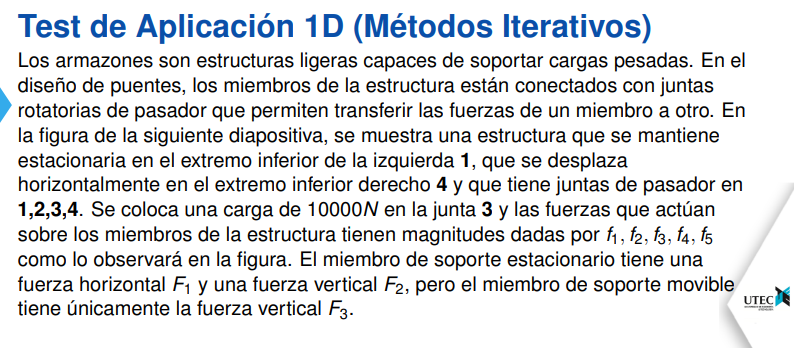

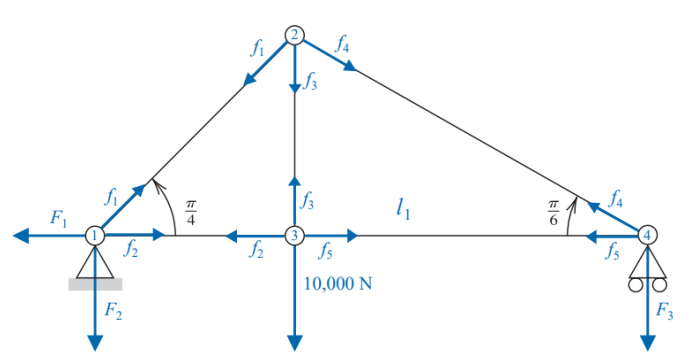

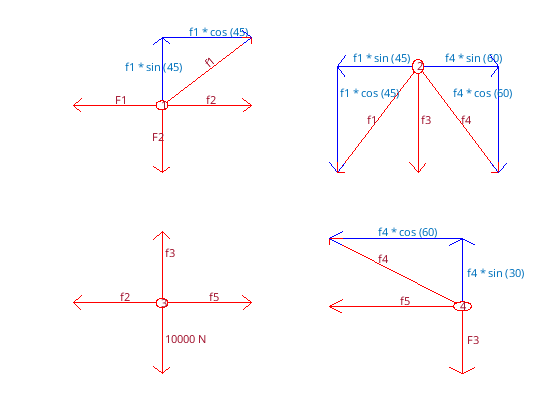


nexttile
grafica1()
nexttile
grafica2()
nexttile
grafica3()
nexttile
grafica4()

Teniendo las fuerzas del punto 1, podemos sacar las siguientes ecuaciones

        
$$\begin{array}{l}
\mathrm{f1}*\sin \left(45\right)=-\mathrm{F2}\\
\mathrm{f1}*\sin \left(45\right)+\mathrm{F2}=0
\end{array}$$
                        
$$\begin{array}{l}
-\mathrm{F1}=\mathrm{f1}*\cos \left(45\right)+\mathrm{f2}\\
\mathrm{f1}*\cos \left(45\right)+\mathrm{f2}+\mathrm{F1}=0
\end{array}$$


Teniendo las fuerzas del punto 2, podemos sacar las siguientes ecuaciones

        
$$\begin{array}{l}
-\mathrm{f3}\;-\;\mathrm{f1}*\cos \left(45\right)\;-\;\mathrm{f4}*\cos \left(60\right)=0\\
\;\mathrm{f1}*\cos \left(45\right)\;+\;\mathrm{f3}+\;\mathrm{f4}*\cos \left(60\right)=0
\end{array}$$
                        
$$\begin{array}{l}
-\mathrm{f1}*\mathrm{sen}\left(45\right)=\mathrm{f4}*\sin \left(60\right)\\
\mathrm{f1}*\mathrm{sen}\left(45\right)\;+\;\mathrm{f4}*\sin \left(60\right)=0
\end{array}$$


Teniendo las fuerzas del punto 3, podemos sacar las siguientes ecuaciones

        
$$\mathrm{f3}=-10000$$
                        
$$\begin{array}{l}
-\mathrm{f2}=\mathrm{f5}\\
\mathrm{f2}+\mathrm{f5}=0
\end{array}$$


Teniendo las fuerzas del punto 4, podemos sacar las siguientes ecuaciones

        
$$\begin{array}{l}
\mathrm{f4}*\sin \left(30\right)=-\mathrm{F3}\\
\mathrm{f4}*\sin \left(30\right)+\mathrm{F3}\;=0
\end{array}$$
                        
$$\begin{array}{l}
-\mathrm{f4}*\cos \left(30\right)-\mathrm{f5}=0\\
\mathrm{f4}*\cos \left(30\right)+\mathrm{f5}=0
\end{array}$$


Las ecuaciones al final serian


$$\begin{array}{l}
\mathrm{f1}*\sin \left(45\right)+\mathrm{F2}=0\\
\mathrm{f1}*\cos \left(45\right)+\mathrm{f2}+\mathrm{F1}=0\\
\;\mathrm{f1}*\cos \left(45\right)\;+\;\mathrm{f3}+\;\mathrm{f4}*\cos \left(60\right)=0\\
\mathrm{f1}*\mathrm{sen}\left(45\right)\;+\;\mathrm{f4}*\sin \left(60\right)=0\\
\mathrm{f3}=-10000\\
\mathrm{f2}+\mathrm{f5}=0\\
\mathrm{f4}*\sin \left(30\right)+\mathrm{F3}\;=0\\
\mathrm{f4}*\cos \left(30\right)+\mathrm{f5}=0
\end{array}$$


Declaración de la sistema de ecuaciones A*f = b

Nota:

sin(45)  = 1/sqrt(2)

cos(45)  = 1/sqrt(2)

sin(60) = sqrt(3)/2

cos(30) = sqrt(3)/2

sin(30) = (1/2)

cos(60) = (1/2)

%          f1      f2 f3        f4      f5 F1 F2 F3
A = [1*(1/sqrt(2))  0  1  1*(1/2)        0  0  0  0;
     0              1  0  0              1  0  0  0;
     0              0  1  0              0  0  0  0;
     1*(1/sqrt(2))  0  0  1*(sqrt(3)/2)  0  0  0  0;
     0              0  0  1*(sqrt(3)/2)  1  0  0  0;
     1*(1/sqrt(2))  1  0  0              0  1  0  0;
     1*(1/sqrt(2))  0  0  0              0  0  1  0;
     0              0  0  1*(1/2)        0  0  0  1
]

A =    0.707106781186547                   0   1.000000000000000   0.500000000000000                   0                   0                   0                   0
                   0   1.000000000000000                   0                   0   1.000000000000000                   0                   0                   0
                   0                   0   1.000000000000000                   0                   0                   0                   0                   0
   0.707106781186547                   0                   0   0.866025403784439                   0                   0                   0                   0
                   0                   0                   0   0.866025403784439   1.000000000000000                   0                   0                   0
   0.707106781186547   1.000000000000000                   0                   0                   0   1.000000000000000                   0                   0
   0.707106781186547          


b = [0; 0; -10000; 0; 0; 0; 0; 0]

b =            0
           0
      -10000
           0
           0
           0
           0
           0


Se hace uso de la función diagom la cual nos retorno entre 0 y 1, donde 0 significa que es diagonalmente dominante y 1 significa que no es diagonalmente dominante

op = diagdom(A)

op =      1


Como se puede apreciar la matriz A del sistema planteado no es diagonalmente dominante, a pesar de reodernar las filas, la matriz A no llegara a ser diagonalmente dominante ya que en un fila solo hay dos valores que son iguales, lo que provoca que siempre se incumpla la propiedad de:

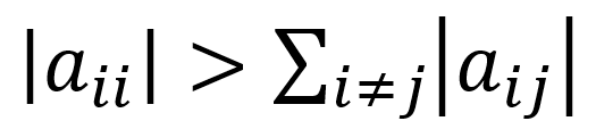

Ahora se calcula el radio espectral para saber si los métodos de Gauss-Seidel y Jacobi convergen

D=diag(diag(A));
L=-tril(A,-1);
U=-triu(A,1);
Tj=inv(D)*(L+U);
Tgs=inv(D-L)*U;

Radio espectral de Jacobi

rho_j=max(abs(eig(Tj)))

rho_j =    0.759835685651593


Como se puede apreciar el radio espectral de Jacobi es menor a uno, por lo tanto si converge en el metodo de Jacobi

Radio espectral de Gauss-Seidel

rho_gs=max(abs(eig(Tgs)))

rho_gs =    0.577350269189626


Como se puede apreciar el radio espectral de Gauss-Seidel es menor a uno, por lo tanto si converge en el metodo de Gauss-Seidel

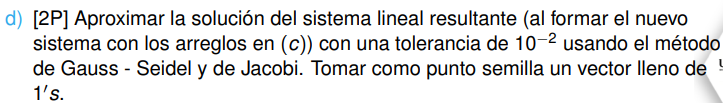

Tol = 10^-4; % Tolerancia
x0 = [1;1;1;1;1;1;1;1] % Punto semilla

x0 =      1
     1
     1
     1
     1
     1
     1
     1


Solución del sistema lineal con el metodo de Jacobi

solucion_jacobi = jacobi(A,b,x0,Tol)

solucion_jacobi = 	1.0e+04 *

   3.345770751587863
  -2.365664794930132
  -1.000000000000000
  -2.731810401666006
   2.365664761290340
  -0.000416453504042
  -2.365817206165332
   1.365817186743389


Solución del sistema lineal con el metodo de Gauss - Seidel

solucion_gausseidel = gausseidel(A,b,x0,Tol)

solucion_gausseidel = 	1.0e+04 *

   3.345770751587863
  -2.365664761290340
  -1.000000000000000
  -2.731810379239479
   2.365817186743389
  -0.000152425453050
  -2.365817186743389
   1.365905189619739


# Funciones:

function [z]=gausseidel(A,b,x0,Tol)
    D=diag(diag(A));
    L=-tril(A,-1);
    U=-triu(A,1);
    Tgs=inv(D-L)*U;
    cgs=inv(D-L)*b;
    error=1;
    while error>Tol
        x1=Tgs*x0+cgs;
        error=norm(x1-x0,inf)/norm(x1,inf);
        x0=x1;
    end
    z = x1;
end
% -------------------------------------------
function [z]=jacobi(A,b,x0,Tol)
    D=diag(diag(A));
    L=-tril(A,-1);
    U=-triu(A,1);
    Tj=inv(D)*(L+U);
    cj=inv(D)*b;
    error=1;
    while error>Tol
        x1=Tj*x0+cj;
        error=norm(x1-x0,inf)/norm(x1,inf);
        x0=x1;
    end
    z = x1;
end
% --------------------------------------------
function op=diagdom(A)
    %op=0: diagonal estrictamente dominante
    %op=1: No es diagonal estrictamente dominante
    [m,n]=size(A);
    op=0;
    if m==n     
        for k=1:m
            if abs(A(k,k))>sum(abs(A(k,:)))-abs(A(k,k))
                op=1;
                break;
            end
        end
    end
end

function z=biseccion2(f,a,b,Tol)
%METODO BISEC 2 CON TOLERANCIA
c=(a+b)/2;
error=(b-a)/2;
z=[a b c f(a) f(b) f(c) error];
N=ceil(log((b-a)/(2*Tol))/log(2));
fprintf('Se necesita %d iteraciones\n',N)
while error>Tol
    if f(a)*f(c)<0
        b=c;
    else
        a=c;
    end
c=(a+b)/2;
error=(b-a)/2;
z=[z; a b c f(a) f(b) f(c) error];
end
raiz=c(1)
logitud=error(1)
end

function z=newton(f,x0,Tol)
syms x
df=diff(f(x));
dfu=matlabFunction(df);
z=[x0];
error=1;
while error >Tol
    x1=x0-f(x0)/dfu(x0);
    z=[z;x1];
    error=abs(x1-x0)/abs(x1);
    x0=x1;
end
end

function m=evalua(F,x0)
syms x y
m=double(subs(F,{x,y},{x0(1),x0(2)}));
end

function z = newtonraphson(F,x0,Tol)
syms x y
dF = jacobian(F(x,y),[x,y])
error=1;
z=[x0' error];
while error>Tol
    x1=x0-inv(evalua(dF,x0))*evalua(F,x0);
    error=norm(x1-x0,inf)/norm(x1,inf);
    z=[z;x1' error];
    x0=x1;
end
end

% Funciones para las graficas, usadas en el item 1D.a

function grafica1()
    a = [3 0];b = [3 3];c = [3 6];d = [0 3];e = [6 3];f = [6 6];
    x = [a(1) b(1) d(1) b(1) e(1) b(1) f(1)];y = [a(2) b(2) d(2) b(2) e(2) b(2) f(2)];
    x_ = [b(1) c(1) f(1)];y_ = [b(2) c(2) f(2)];
    g = [2.7 0.3];f = [3 0];h = [3.3 0.3];
    x1 = [g(1) f(1) h(1)];y1 = [g(2) f(2) h(2)];
    g1 = [2.7 5.7];f1 = [3 6];h1 = [3.3 5.7];
    x2 = [g1(1) f1(1) h1(1)];y2 = [g1(2) f1(2) h1(2)];
    g2 = [0.3 3.3];f2 = [0 3];h2 = [0.3 2.7];
    x3 = [g2(1) f2(1) h2(1)];y3 = [g2(2) f2(2) h2(2)];
    g3 = [5.7 3.3];f3 = [6 3];h3 = [5.7 2.7];
    x4 = [g3(1) f3(1) h3(1)];y4 = [g3(2) f3(2) h3(2)];
    g4 = [5.7 6];f4 = [6 6];h4 = [6 5.7];
    x5 = [g4(1) f4(1) h4(1)];y5 = [g4(2) f4(2) h4(2)];
    g5 = [5.7 6.3];f5 = [6 6];h5 = [5.7 5.7];
    x6 = [g5(1) f5(1) h5(1)];y6 = [g5(2) f5(2) h5(2)];
    rectas = line(x,y);
    rectas.Color='red';
    text(4.5,4.8,"f1","Rotation",40,"FontSize",8,"Color",[0.6350 0.0780 0.1840])
    text(1.4,3.25,"F1","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    text(4.5,3.25,"f2","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    text(2.65,1.6,"F2","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    des_f1 = line(x_,y_);des_f1.Color='blue';
    text(3.9,6.25,"f1 * cos (45)","FontSize",8,"Color",[0 0.4470 0.7410])
    text(1.75,4.7,"f1 * sin (45)","FontSize",8,"Color",[0 0.4470 0.7410])
    flecha1 = line(x1,y1);flecha1.Color = 'red';
    flecha1 = line(x2,y2);flecha1.Color = 'blue';
    flecha2 = line(x3,y3);flecha2.Color = 'red';
    flecha3 = line(x4,y4);flecha3.Color = 'red';
    flecha4 = line(x5,y5);flecha4.Color = 'red';
    flecha5 = line(x6,y6);flecha5.Color = 'blue';
    x_center = 3;y_center = 3;radius = 0.2;
    t = 0:pi/50:2*pi;x__=radius*cos(t)+x_center;y__=radius*sin(t)+y_center;
    patch(x__,y__,'white',"EdgeColor",'red');
    text(2.95,3.01,"1","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    axis off
    end
    
    function grafica2()
    a = [0 0];b = [3 3];c = [3 0];d = [6 0];e = [0 3];f = [6 3];g = [6 0];
    x = [a(1) b(1) c(1) b(1) d(1)];y = [a(2) b(2) c(2) b(2) d(2)];
    x_ = [a(1) e(1) f(1) g(1)];y_ = [a(2) e(2) f(2) g(2)];
    g = [2.7 0.3];f = [3 0];h = [3.3 0.3];
    x1 = [g(1) f(1) h(1)];y1 = [g(2) f(2) h(2)];
    g1 = [-0.3 0.3];f1 = [0 0];h1 = [0.3 0.3];
    x2 = [g1(1) f1(1) h1(1)];y2 = [g1(2) f1(2) h1(2)];
    g2 = [0.3 3.3];f2 = [0 3];h2 = [0.3 2.7];
    x3 = [g2(1) f2(1) h2(1)];y3 = [g2(2) f2(2) h2(2)];
    g3 = [5.7 3.3];f3 = [6 3];h3 = [5.7 2.7];
    x4 = [g3(1) f3(1) h3(1)];y4 = [g3(2) f3(2) h3(2)];
    g4 = [0 0.3];f4 = [0 0];h4 = [0.3 0];
    x5 = [g4(1) f4(1) h4(1)];y5 = [g4(2) f4(2) h4(2)];
    g5 = [6 0.3];f5 = [6 0];h5 = [5.7 0];
    x6 = [g5(1) f5(1) h5(1)];y6 = [g5(2) f5(2) h5(2)];
    g6 = [5.7 0.3];f6 = [6 0];h6 = [6.3 0.3];
    x7 = [g6(1) f6(1) h6(1)];y7 = [g6(2) f6(2) h6(2)];
    rectas = line(x,y);rectas.Color='red';
    text(3.1,1.5,"f3","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    text(1.1,1.5,"f1","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    text(4.6,1.5,"f4","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    des_f1 = line(x_,y_);des_f1.Color='blue';
    text(4,3.25,"f4 * sin (60)","FontSize",8,"Color",[0 0.4470 0.7410])
    text(0.6,3.25,"f1 * sin (45)","FontSize",8,"Color",[0 0.4470 0.7410])
    text(0.1,2.25,"f1 * cos (45)","FontSize",8,"Color",[0 0.4470 0.7410])
    text(4.3,2.25,"f4 * cos (60)","FontSize",8,"Color",[0 0.4470 0.7410])
    flecha1 = line(x1,y1);flecha1.Color = 'red';
    flecha1 = line(x2,y2);flecha1.Color = 'blue';
    flecha2 = line(x3,y3);flecha2.Color = 'blue';
    flecha3 = line(x4,y4);flecha3.Color = 'blue';
    flecha4 = line(x5,y5);flecha4.Color = 'red';
    flecha5 = line(x6,y6);flecha5.Color = 'red';
    flecha6 = line(x7,y7);flecha6.Color = 'blue';
    x_center = 3;y_center = 3;radius = 0.2;t = 0:pi/50:2*pi;
    x__=radius*cos(t)+x_center;y__=radius*sin(t)+y_center;
    patch(x__,y__,'white',"EdgeColor",'red');
    text(2.95,3.01,"2","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    axis off
    end
    
    function grafica3()
    a = [3 0];b = [3 3];c = [0 3];d = [6 3];e = [3 6];
    x = [a(1) b(1) c(1) b(1) d(1) b(1) e(1)];y = [a(2) b(2) c(2) b(2) d(2) b(2) e(2)];
    g = [2.7 0.3];f = [3 0];h = [3.3 0.3];
    x1 = [g(1) f(1) h(1)];y1 = [g(2) f(2) h(2)];
    g1 = [0.3 6];f1 = [0 6];h1 = [0 5.7];
    x2 = [g1(1) f1(1) h1(1)];y2 = [g1(2) f1(2) h1(2)];
    g2 = [5.7 3.3];f2 = [6 3];h2 = [5.7 2.7];
    x3 = [g2(1) f2(1) h2(1)];y3 = [g2(2) f2(2) h2(2)];
    g3 = [2.7 5.7];f3 = [3 6];h3 = [3.3 5.7];
    x4 = [g3(1) f3(1) h3(1)];y4 = [g3(2) f3(2) h3(2)];
    g4 = [0.3 3.3];f4 = [0 3];h4 = [0.3 2.7];
    x5 = [g4(1) f4(1) h4(1)];y5 = [g4(2) f4(2) h4(2)];
    rectas = line(x,y);rectas.Color='red';
    text(1.6,3.25,"f2","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    text(3.1,1.5,"10000 N","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    text(3.1,5.1,"f3","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    text(4.6,3.25,"f5","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    flecha1 = line(x1,y1);flecha1.Color = 'red';
    flecha2 = line(x3,y3);flecha2.Color = 'red';
    flecha3 = line(x4,y4);flecha3.Color = 'red';
    flecha4 = line(x5,y5);flecha4.Color = 'red';
    x_center = 3;y_center = 3;radius = 0.2;t = 0:pi/50:2*pi;
    x__=radius*cos(t)+x_center;y__=radius*sin(t)+y_center;
    patch(x__,y__,'white',"EdgeColor",'red');
    text(2.95,3.01,"3","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    axis off
    end
    
    function grafica4()
    a = [3 0];b = [3 3];c = [0 3];d = [0 6];e = [3 6];
    x = [a(1) b(1) c(1) b(1) d(1)];y = [a(2) b(2) c(2) b(2) d(2)];
    x_ = [b(1) e(1) d(1)];y_ = [b(2) e(2) d(2)];
    g = [2.7 0.3];f = [3 0];h = [3.3 0.3];
    x1 = [g(1) f(1) h(1)];y1 = [g(2) f(2) h(2)];
    g1 = [0.3 6];f1 = [0 6];h1 = [0 5.7];
    x2 = [g1(1) f1(1) h1(1)];y2 = [g1(2) f1(2) h1(2)];
    g2 = [0.3 3.3];f2 = [0 3];h2 = [0.3 2.7];
    x3 = [g2(1) f2(1) h2(1)];y3 = [g2(2) f2(2) h2(2)];
    g3 = [2.7 5.7];f3 = [3 6];h3 = [3.3 5.7];
    x4 = [g3(1) f3(1) h3(1)];y4 = [g3(2) f3(2) h3(2)];
    g4 = [0.3 6.3];f4 = [0 6];h4 = [0.3 5.7];
    x5 = [g4(1) f4(1) h4(1)];y5 = [g4(2) f4(2) h4(2)];
    rectas = line(x,y);rectas.Color='red';
    text(1.6,3.25,"f5","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    text(3.1,1.5,"F3","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    text(1.1,5.1,"f4","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    des_f1 = line(x_,y_);des_f1.Color='blue';
    text(3.1,4.5,"f4 * sin (30)","FontSize",8,"Color",[0 0.4470 0.7410])
    text(1.1,6.29,"f4 * cos (60)","FontSize",8,"Color",[0 0.4470 0.7410])
    flecha1 = line(x1,y1);flecha1.Color = 'red';
    flecha1 = line(x2,y2);flecha1.Color = 'red';
    flecha2 = line(x3,y3);flecha2.Color = 'red';
    flecha3 = line(x4,y4);flecha3.Color = 'blue';
    flecha4 = line(x5,y5);flecha4.Color = 'blue';
    x_center = 3;y_center = 3;radius = 0.2;t = 0:pi/50:2*pi;
    x__=radius*cos(t)+x_center;y__=radius*sin(t)+y_center;
    patch(x__,y__,'white',"EdgeColor",'red');
    text(2.95,3.01,"4","FontSize",8,"Color",[0.6350 0.0780 0.1840])
    axis off
    end